# Experiment 2: CNN (Whole Image) - Using imagePretrainedNetwork (ResNet-18)

## Clean environment

close all;
clear variables;
clc;
rng(42);

## Set folder path

folder = "C:\Users\u3253992\workspace\computer-vision\assignment_1\u3253992_assignment_1\data\CUB_200_2011_Subset20classes\";

## Load dataset

[trainingImageNames, validationImageNames, testImageNames, classNames, imageClassLabels] = loadDataset(folder);
numClasses = height(classNames);

## Create datastores

disp('Training set class distribution:');

Training set class distribution:


trainingImageDS = createImageDatastore(trainingImageNames, folder);

    Label    Count
    _____    _____

     001      36  
     002      36  
     003      35  
     004      36  
     005      26  
     006      25  
     007      30  
     008      29  
     009      35  
     010      36  
     011      36  
     012      34  
     013      36  
     014      36  
     015      35  
     016      35  
     017      34  
     018      26  
     019      35  
     020      35  




disp('Validation set class distribution:');

Validation set class distribution:


validationImageDS = createImageDatastore(validationImageNames, folder);

    Label    Count
    _____    _____

     001       6  
     002      12  
     003      12  
     004      12  
     005       9  
     006       8  
     007      12  
     008      10  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      12  
     016      12  
     017      12  
     018      10  
     019      12  
     020      12  




disp('Test set class distribution:');

Test set class distribution:


testImageDS = createImageDatastore(testImageNames, folder);

    Label    Count
    _____    _____

     001      12  
     002      12  
     003      11  
     004      12  
     005       9  
     006       8  
     007      12  
     008       9  
     009      12  
     010      12  
     011      12  
     012      11  
     013      12  
     014      12  
     015      11  
     016      11  
     017      11  
     018       9  
     019      12  
     020      12  



## Resize image datastores and combine them with the labels

targetSize = [224, 224];   % ResNet18 input size

trainCDS = resizeCombineDatastore(trainingImageDS, targetSize);
valCDS = resizeCombineDatastore(validationImageDS, targetSize);
testCDS = resizeCombineDatastore(testImageDS, targetSize);

## Show example images

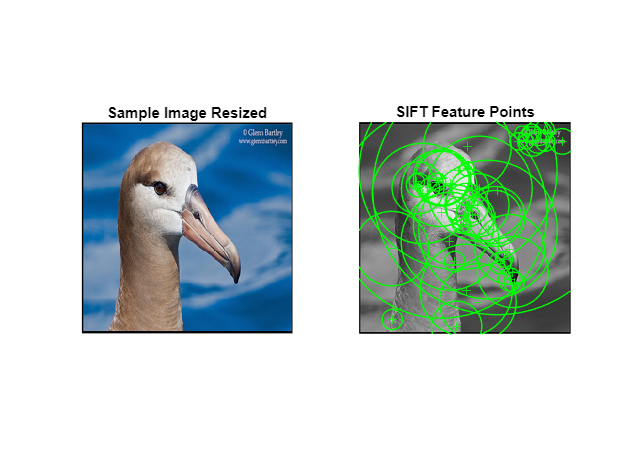

ans = 0

showImageFeatures(trainCDS)

## Enables GPU

[device, useGPU] = enableGPU();

✅ GPU found and ready:
  CUDADevice with properties:

                 Name: 'NVIDIA GeForce RTX 3070'
                Index: 1 (of 1)
    ComputeCapability: '8.6'
          DriverModel: 'WDDM'
          TotalMemory: 8589410304 (8.59 GB)
      AvailableMemory: 7443034112 (7.44 GB)
      DeviceAvailable: true
       DeviceSelected: true

  Show 

## Load pretrained network using imagePretrainedNetwork

net = imagePretrainedNetwork("resnet18", Weights="none", NumClasses=numClasses);

net.Layers

ans =   70×1 Layer array with layers:

     1   'data'                  Image Input                  224×224×3 images with 'zscore' normalization
     2   'conv1'                 2-D Convolution              64 7×7×3 convolutions with stride [2  2] and padding [3  3  3  3]
     3   'bn_conv1'              Batch Normalization          Batch normalization with 64 channels
     4   'conv1_relu'            ReLU                         ReLU
     5   'pool1'                 2-D Max Pooling              3×3 max pooling with stride [2  2] and padding [1  1  1  1]
     6   'res2a_branch2a'        2-D Convolution              64 3×3×64 convolutions with stride [1  1] and padding [1  1  1  1]
     7   'bn2a_branch2a'         Batch Normalization          Batch normalization with 64 channels
     8   'res2a_branch2a_relu'   ReLU                         ReLU
     9   'res2a_branch2b'        2-D Convolution              6

## Training options

options = trainingOptions('adam', ...
    'InitialLearnRate', 0.0001, ...
    'MiniBatchSize', 48, ...
    'MaxEpochs', 20, ...
    'Shuffle', 'every-epoch', ...
    'ValidationData', valCDS, ...
    'ValidationFrequency', 5, ...
    'Verbose', true, ...
    'Metrics',"accuracy", ...
    'Plots', 'training-progress');

## Train the network

    Iteration    Epoch    TimeElapsed    LearnRate    TrainingLoss    ValidationLoss    TrainingAccuracy    ValidationAccuracy
    _________    _____    ___________    _________    ____________    ______________    ________________    __________________
            0        0       00:00:02       0.0001                             3.007                                    3.6036
            1        1       00:00:02       0.0001           3.342                                10.417                      
            5        1       00:00:06       0.0001          3.0906            3.0432                12.5                6.3063
           10        1       00:00:10       0.0001          2.9631            3.2207              8.3333                5.4054
           15        2       00:00:13       0.0001          2.5308            3.3388              29.167                6.7568
           20        2       00:00:15       0.0001           2.214            3.3081               31.25       

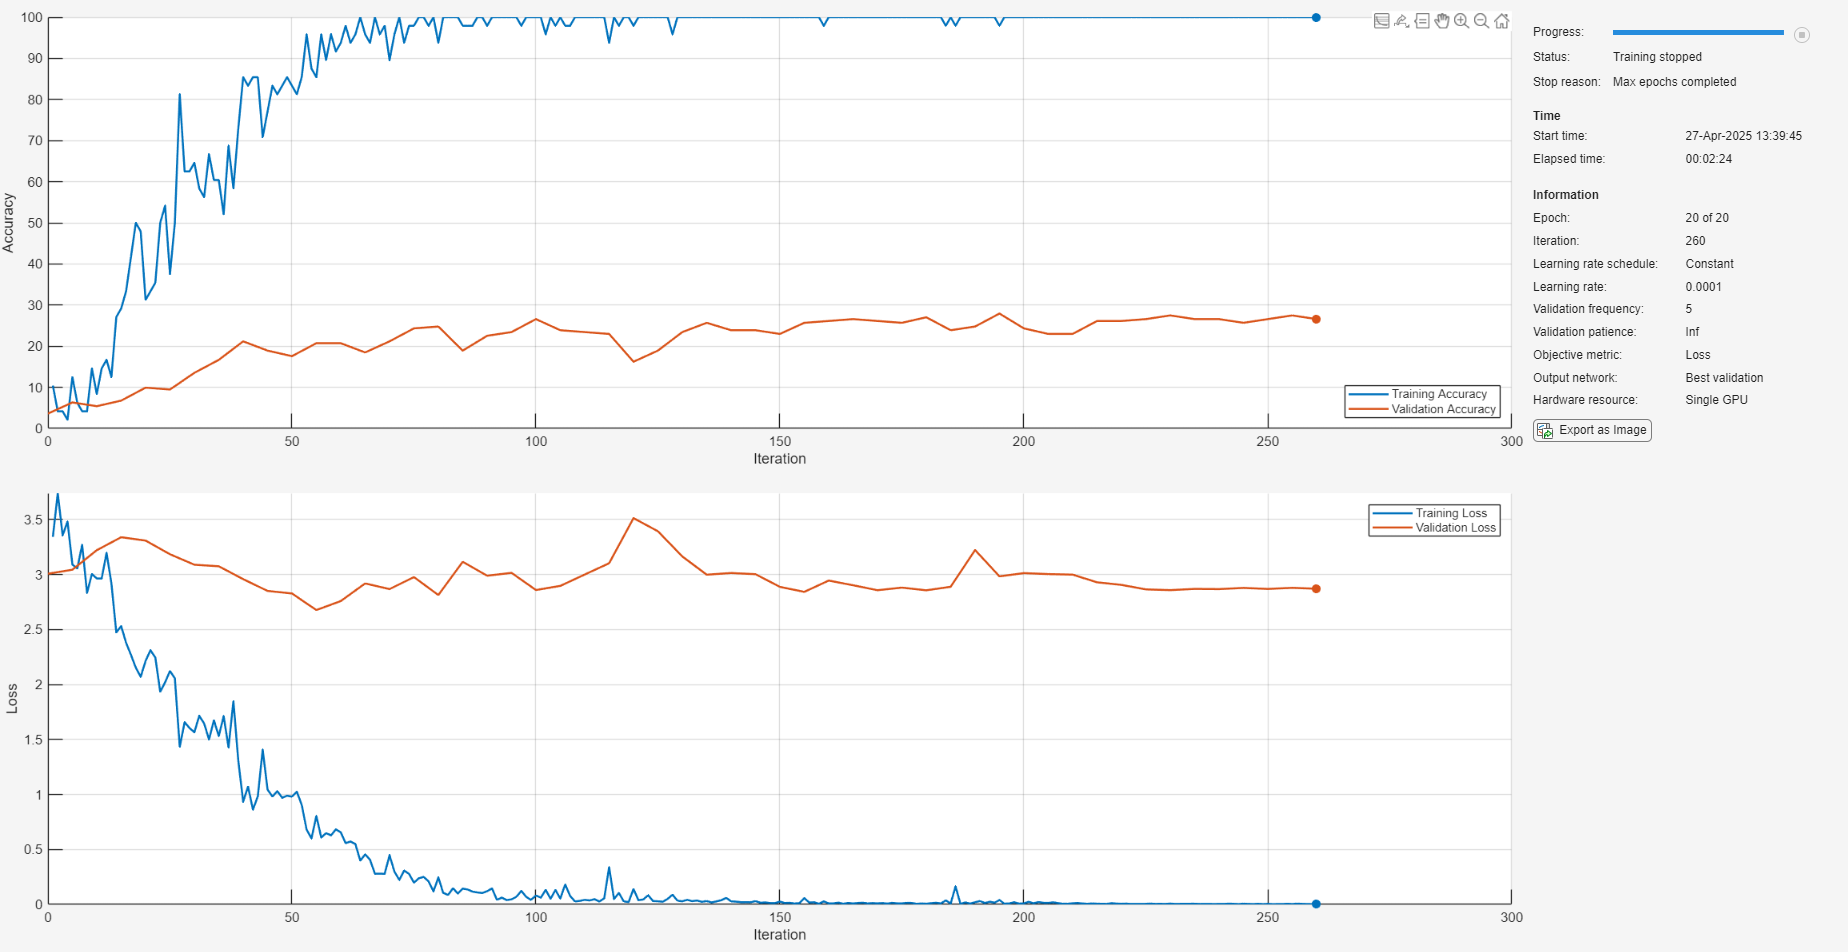

trainedNet = trainnet(trainCDS, net, "crossentropy", options);

## Evaluate the model

scoresTest = minibatchpredict(trainedNet, testCDS)

scoresTest = 222×20 single matrix
    0.0436    0.0307    0.0042    0.0011    0.0044    0.2661    0.0051    0.0185    0.1166    0.1513    0.0102    0.0145    0.2321    0.0264    0.0136    0.0054    0.0108    0.0066    0.0346    0.0045
    0.0547    0.5756    0.1008    0.0007    0.0092    0.0366    0.0115    0.0788    0.0235    0.0266    0.0480    0.0043    0.0030    0.0026    0.0102    0.0004    0.0030    0.0017    0.0025    0.0064
    0.2358    0.0188    0.0668    0.0007    0.0006    0.0093    0.0004    0.5703    0.0133    0.0020    0.0339    0.0008    0.0002    0.0258    0.0106    0.0002    0.0010    0.0010    0.0011    0.0073
    0.1253    0.0687    0.0194    0.0003    0.0429    0.1049    0.0067    0.0026    0.0017    0.2978    0.1930    0.0375    0.0364    0.0006    0.0011    0.0002    0.0536    0.0018    0.0013    0.0043
    0.2129    0.2411    0.0201    0.0015    0.0054    0.1252    0.0125    0.0462    0.0393    0.1195    0.0457    0.0125    0.0298    0.0125    0.0118    0.0042  

pred = scores2label(scoresTest,classNames.className);
[~, yPred] = max(scoresTest, [], 2);
% disp("Predictions");
% disp(yPred);
yTest = str2double(string(testImageDS.Labels))

yTest =      1
     1
     1
     1
     1
     1
     1
     1
     1
     1


accuracy = sum(yPred == yTest) / numel(yTest);
disp(accuracy)

    0.1802



## Plot confusion matrix

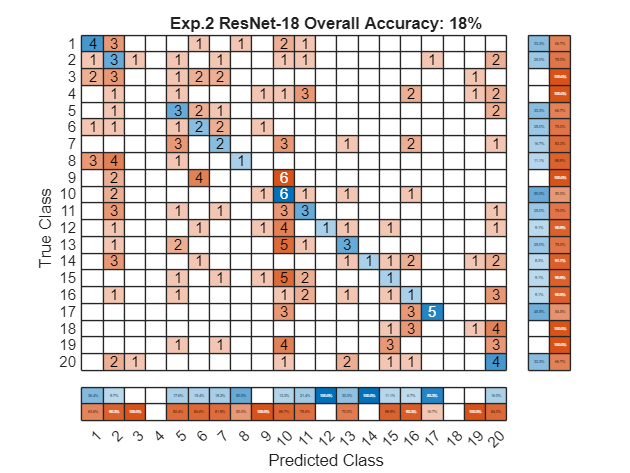

Classwise Recognition Rates:
   33.3000
   25.0000
         0
         0
   33.3000
   25.0000
   16.7000
   11.1000
         0
   50.0000
   25.0000
    9.1000
   25.0000
    8.3000
    9.1000
    9.1000
   45.5000
         0
         0
   33.3000



plotConfusionMatrix(yTest, yPred, "Exp.2 ResNet-18 Overall Accuracy: " + string(round(accuracy*100, 1)) + "%");